# Sensing System - revD

Changes since previous version:

- removed SIMULINK model integration as it was very finicky

To-Do's:

- significantly simplify the first step of loading samples into the sensing subsystem itself to be more in line with what will happen on the USRP

- Modify the simulator to be able to run off of a JSON configuration instead of having a function for each piece

## Key parts of the Sensing Subystem

### Debugging Capability

For each debuger array, the format will be as follows:

- 1st column - number of frames computed at that point

- 2nd column - number of chirps computed at that point

- remainder of columns - data taken

## Generate a Spectogram

Steps to generate spectoram:

- reshape into 1us wide windows to sample frequency at (ex: 50 samples per 1us when sampling at 50 Msps)

- reduce the number of samples in the window to the desired size of fft (ex: 32 bits)

- window the sample signal

- perform fft

### Revised Linear Model Computation:

link to resourse used to compute linear model: [https://online.stat.psu.edu/stat462/node/132/](https://online.stat.psu.edu/stat462/node/132/) 

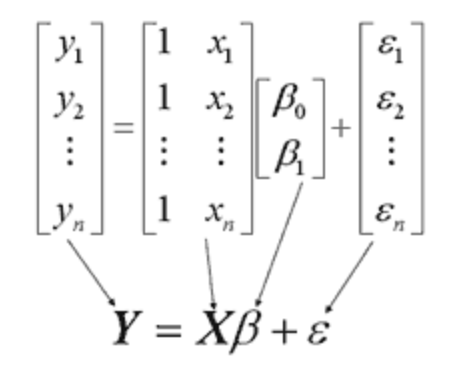

solving for this with out the Epsilon term though


$$\beta = (X^{T}X)^{-1}X^{T}Y$$


## Additional parameter settings for slope and duration

clear;
use_custom_settings = true; %uses the settings below instead of the settings in the config file
slope_MHz_us = 45;
chirp_cycle_period_us = 55;

## Initialize the simulator

simulator = Simulator_revB();
kristen_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
david_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
 file_path = "20MHz.json";
% file_path = "100MHz.json";
% file_path = "1GHz.json";
% file_path = "4GHz.json";
simulator.load_params_from_JSON(david_path + file_path);

if use_custom_settings
    %set new parameters for victim
    simulator.Victim.FrequencySlope_MHz_us = slope_MHz_us;
    simulator.Victim.ChirpCycleTime_us = chirp_cycle_period_us;
    simulator.Victim.compute_calculated_vals();

    %set attacker parameters
    simulator.Attacker.Subsystem_tracking.FrequencySlope_MHz_us = slope_MHz_us;
    simulator.Attacker.Subsystem_tracking.ChirpCycleTime_us = chirp_cycle_period_us;
    simulator.Attacker.Subsystem_tracking.compute_calculated_vals();
end

%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default attacker, and victim positions and velocities
simulator.load_realistic_attacker_and_victim_position_and_velocity();

%print out key parameters
simulator.Victim.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 45.00 MHz/us
	 Idle Time: 			 31.15 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 1084.78 MHz
	 Chirp Sampling Bandwidth: 	 780.07 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 55.25 us
	 Chirp Wavelength: 		 3.89 mm



simulator.Victim.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.37 ms
	 Active Frame Time 		 7.07 ms


simulator.Victim.print_performance_specs;

Performance Specifications
	 Max Range 			 12.30 m
	 Range Resolution 		 0.19 m
	 Max Velocity 			 17.62 m/s
	 Velocity Resolution 		 0.28 m/s


simulator.Victim.print_FMCW_specs;

FMCW Specifications
	 FMCW sampling rate 		 1085.45 MHz
	 Downsampling factor 		 294
	 Sweep time 			 24.11 us
	 Samples per chirp 		 59976.00 


## Initialize the Target

simulator.load_target_realistic(50,15);

## Initialize the Victim and Simulation Parameters

%specify the number of frames and chirps to compute
frames_to_compute = 10;

%specify whether or not to record a movie of the range-doppler plot
record_movie = false;
simulator.Victim.Radar_Signal_Processor.configure_movie_capture(frames_to_compute,record_movie);

%pre-compute the victim's chirps
simulator.Victim.precompute_radar_chirps();

## Initialize the Attacker

%initialize the attacker parameters
simulator.Attacker.initialize_attacker(...
                        simulator.Victim.FMCW_sampling_rate_Hz * 1e-6,...
                        simulator.Victim.StartFrequency_GHz,...
                        simulator.Victim.Chirp_Tx_Bandwidth_MHz);

%initialize the sensing subsystem's debugger
simulator.Attacker.Subsystem_spectrum_sensing.initialize_debugger(1,simulator.Victim,frames_to_compute);
%set to change 1 to zero to disable

%specify the type of emulation ("target", 
        % "velocity spoof - noisy", 
        % "velocity spoof - similar velocity",
        % "range spoof - similar slope")

%attack_type = "range spoof - similar slope";
attack_type = "range spoof - similar slope,velocity spoof - noisy";
%attack_type = "target";
%initialize the attacker
simulator.Attacker.Subsystem_attacking.set_attack_mode(attack_type);

%if it is desired to specify a specific attack location
%simulator.Attacker.Subsystem_attacking.set_desired_attack_location(100,7);

## Rewritten Attacker Code

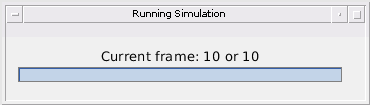

simulator.run_simulation_with_attack(frames_to_compute,true);

% %print out the relevant information
fprintf("Average Frame Duration: %5.3f us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_frame_duration);

Average Frame Duration: 33373.783 us

fprintf("Average Chirp Duration: %3.3f us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_chirp_duration);

Average Chirp Duration: 55.255 us

fprintf("Average Slope: %1.3f MHz/us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_slope);

Average Slope: 44.982 MHz/us

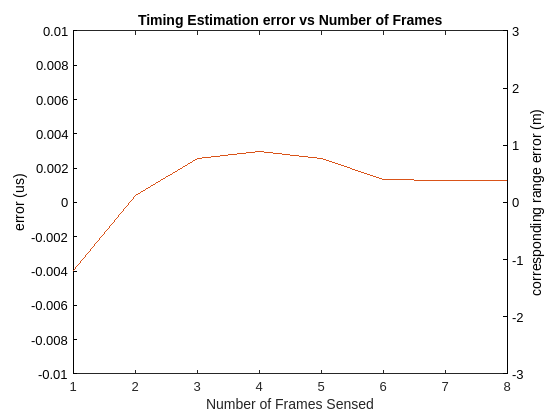

%compare the predicted frame start times with the actual frame start times
actual_frame_start_times = (3:frames_to_compute).' * simulator.Victim.FramePeriodicity_ms * 1e3 ... 
                                + simulator.Victim.IdleTime_us;
predicted_start_time_errors = simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.captured_frames(2:...
    simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.num_captured_frames,7) ...
                                - actual_frame_start_times;


errors_in_range = predicted_start_time_errors * 1e-6 * physconst("LightSpeed");

clf;
plot(predicted_start_time_errors);
title("Timing Estimation error vs Number of Frames")
xlabel("Number of Frames Sensed")
ylabel("error (us)")
ylim([-10 * 1e-3, 10 * 1e-3])

%add in the axis for range error
yyaxis right
plot(errors_in_range)
ylabel("corresponding range error (m)")
set(gca,"YColor", 'black')
ylim([-3, 3]);

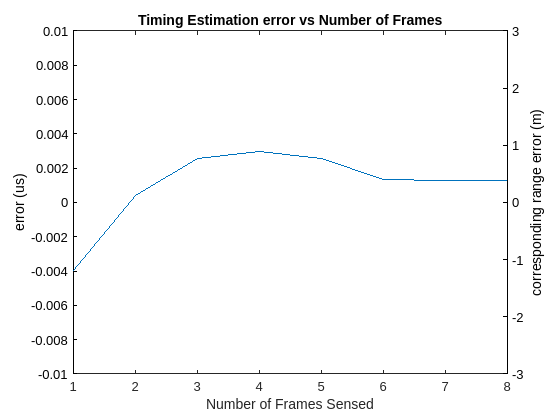

cla

## Run the Debugger if enabled

if simulator.Attacker.Subsystem_spectrum_sensing.Debugger.enabled
    simulator.Attacker.Subsystem_spectrum_sensing.debugger_compute_errors(simulator.Victim);
    [summary_table] = simulator.Attacker.Subsystem_spectrum_sensing.debugger_summarize_errors();
    summary_table
end

summary_table = 4×3 table
                                  Mean        Variance        MSE    
                               __________    __________    __________

    Detected Times (us)        0.00096999    0.00041122    0.00041214
    Detected Frequencies        -0.043649       0.83273       0.83458
    Computed Slope              -0.017914    0.00042963    0.00074926
    Computed Intercept (us)    -0.0035883    2.2995e-05    3.5802e-05
